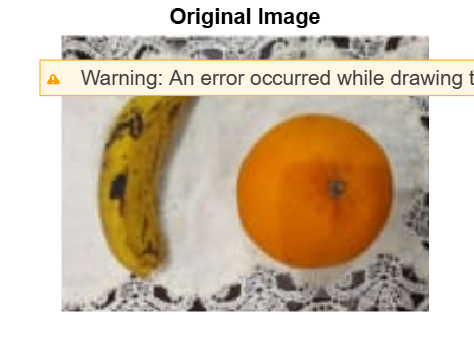

clc; clear; close all;

% Load Image
img = imread('fruit.png'); % Ensure correct image
figure, imshow(img), title('Original Image');

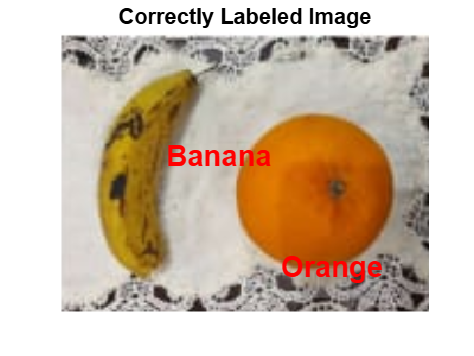


% Convert to HSV Color Space
hsvImg = rgb2hsv(img);
hue = hsvImg(:,:,1);

% Define Color Ranges
bananaMask = (hue > 0.10 & hue < 0.20); % Yellow range for banana
orangeMask = (hue > 0.02 & hue < 0.08); % Orange range for orange

% Remove Small Objects
bananaMask = bwareaopen(bananaMask, 1500);
orangeMask = bwareaopen(orangeMask, 1500);

% Get Properties of Detected Objects
bananaProps = regionprops(bananaMask, 'BoundingBox', 'Centroid', 'Area');
orangeProps = regionprops(orangeMask, 'BoundingBox', 'Centroid', 'Area');

% Display Image
figure, imshow(img), title('Correctly Labeled Image');
hold on;

% Label Banana
if ~isempty(bananaProps)
    [~, idx] = max([bananaProps.Area]); % Select largest banana
    bananaCentroid = bananaProps(idx).Centroid;
    text(bananaCentroid(1), bananaCentroid(2) + 20, 'Banana', ...
        'Color', 'r', 'FontSize', 14, 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
end

% Label Orange
if ~isempty(orangeProps)
    [~, idx] = max([orangeProps.Area]); % Select largest orange
    orangeCentroid = orangeProps(idx).Centroid;
    text(orangeCentroid(1), orangeCentroid(2) + 20, 'Orange', ...
        'Color', 'r', 'FontSize', 14, 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
end

hold off;